# Possible Ideas and Useful Information for Mapping to Rigid Body

We employ DFAG as a test run here as we grab some useful information and consider how to use it to go to a rigid body map.  There are 3-4 parameters of the rigid body: the well depths of the SC, aromatic, and possible back bone beads, and the radius of the sidechain.  Maybe also the location of the SC beads?

We know from PMF calculations that there is a change of ~2 kT for the SCs alone and ~12 kT for the aromatics alone (for DFAG)

The backbone well is a *question* -- one might try doing a PMF calculation of the edge-edge aromatics as well? (Alternatively set it to always be the same thing because it won't change much as the cores do).

We can also calculate the solvent accessible surface area and the approximate volume of the side chains.  If we make the utterly gratuitous assumption that the SASA is a sphere, that gets us an approximate radius for the sphere in question.

You can also compute the radius from the *volume*.

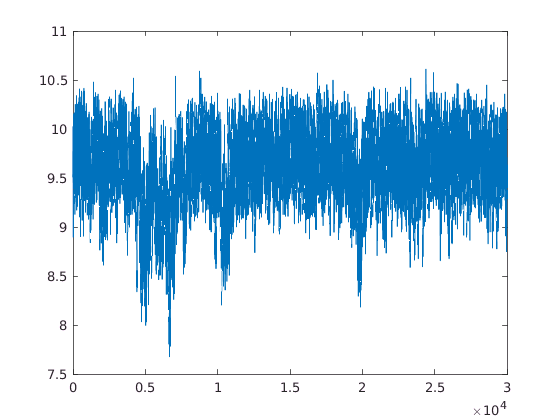

sasafile = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab_NP_water/5_md/sasaSC.xvg';
sasa = importdata(sasafile,' ',23);
sasadata = sasa.data;
figure()
plot(sasadata(:,1),sasadata(:,2))

SA = mean(sasadata(:,2))

SA = 9.5896

r = sqrt(SA/(4*pi))

r = 0.8736

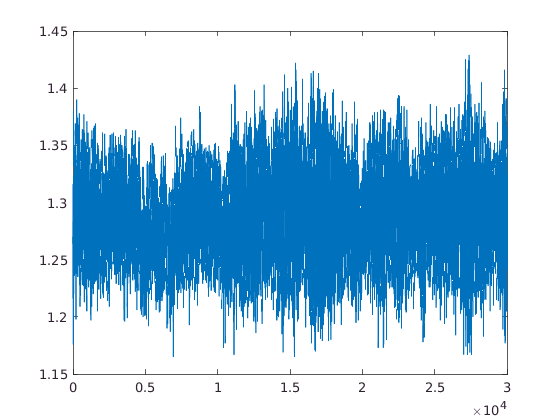

volfile = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab_NP_water/5_md/volSC.xvg';
vol = importdata(volfile,' ',24);
voldata = vol.data;
figure()
plot(voldata(:,1),voldata(:,2))

vol = mean(voldata(:,2))

vol = 1.2860

r = ((3/4)*vol/pi)^(1/3)

r = 0.6746

We can also calculate the location of the COM of each SC compared to the COM of the molecule.

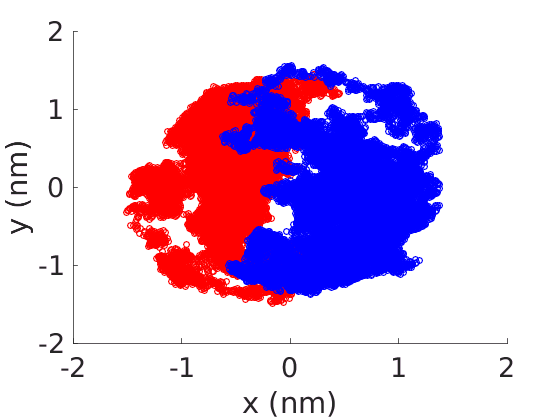

commolsfile = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab_NP_water/5_md/comMols.xvg';
comSC1file = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab_NP_water/5_md/comSC1.xvg';
comSC2file = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab_NP_water/5_md/comSC2.xvg';
commols = importdata(commolsfile,'\t',25);
comSC1 = importdata(comSC1file,'\t',25);
comSC2 = importdata(comSC2file,'\t',25);
rcomSC1 = comSC1.data - commols.data;
rcomSC2 = comSC2.data - commols.data;
figure()
hold on
scatter(rcomSC1(:,2),rcomSC1(:,3),20,'r');
scatter(rcomSC2(:,2),rcomSC2(:,3),20,'b');
xlabel('x (nm)')
ylabel('y (nm)')
set(gca,'fontsize',20)

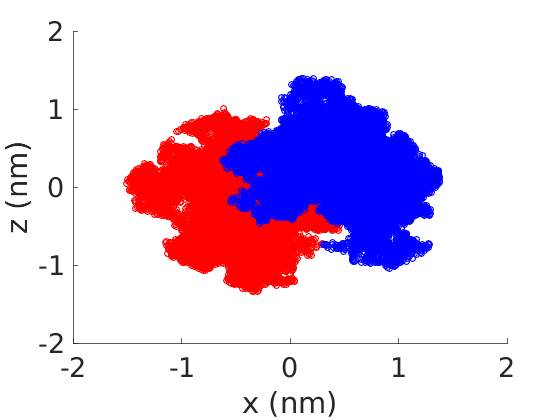

figure()
hold on
scatter(rcomSC1(:,2),rcomSC1(:,4),20,'r');
scatter(rcomSC2(:,2),rcomSC2(:,4),20,'b');
xlabel('x (nm)')
ylabel('z (nm)')
set(gca,'fontsize',20)

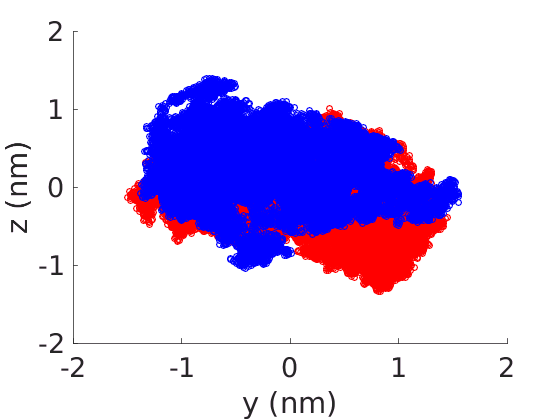

figure()
hold on
scatter(rcomSC1(:,3),rcomSC1(:,4),20,'r');
scatter(rcomSC2(:,3),rcomSC2(:,4),20,'b');
xlabel('y (nm)')
ylabel('z (nm)')
set(gca,'fontsize',20)

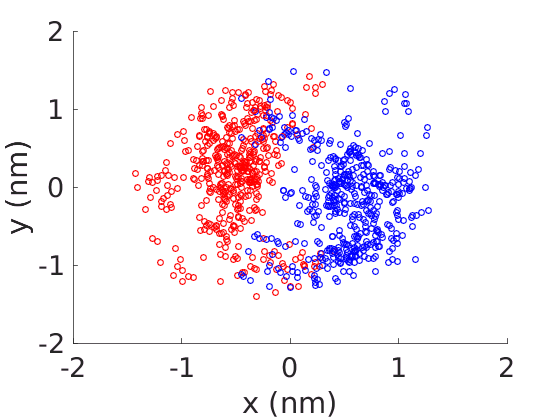

figure()
hold on
scatter3(rcomSC1(1:100:end,2),rcomSC1(1:100:end,3),rcomSC1(1:100:end,4),20,'r');
scatter3(rcomSC2(1:100:end,2),rcomSC2(1:100:end,3),rcomSC2(1:100:end,4),20,'b');
xlabel('x (nm)')
ylabel('y (nm)')
zlabel('z (nm)')
set(gca,'fontsize',20)

Okay, but really we're interested in the distance *along* the principal axis as well as the distance *radially away from* the principal axis.  Define the relevant "principal axis" as the vector pointing from one end aromatic to the other end aromatic.

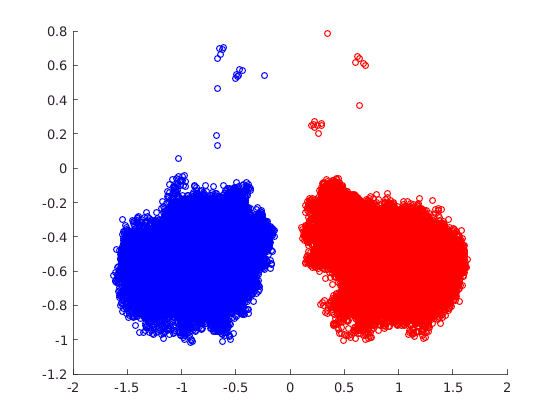

comarom1file = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab_NP_water/5_md/comarom1.xvg';
comarom2file = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab_NP_water/5_md/comarom2.xvg';
comarom1 = importdata(comarom1file,'\t',25);
comarom2 = importdata(comarom2file,'\t',25);
pvecs = comarom1.data(:,2:end) - comarom2.data(:,2:end);
vpar1 = bsxfun(@times,pvecs,dot(pvecs,rcomSC1(:,2:end),2)./sqrt(sum(pvecs.^2,2)));
vperp1 = rcomSC1(:,2:end) - vpar1;
vpar2 = bsxfun(@times,pvecs,dot(pvecs,rcomSC2(:,2:end),2)./sqrt(sum(pvecs.^2,2)));
vperp2 = rcomSC2(:,2:end) - vpar2;
xvals1 = dot(pvecs,rcomSC1(:,2:end),2)./sqrt(sum(pvecs.^2,2));
yvals1 = sqrt(sum(vperp1.^2,2))./sign(dot(vpar1,vperp1,2));
xvals2 = dot(pvecs,rcomSC2(:,2:end),2)./sqrt(sum(pvecs.^2,2));
yvals2 = sqrt(sum(vperp2.^2,2))./sign(dot(vpar2,vperp2,2));
figure()
hold on
scatter(xvals1,yvals1,20,'r')
scatter(xvals2,yvals2,20,'b')

parloc1 = mean(xvals1)

parloc1 = 0.8149

parloc2 = mean(xvals2)

parloc2 = -0.8391

perploc1 = mean(yvals1)

perploc1 = -0.4705

perploc2 = mean(yvals2)

perploc2 = -0.4962

stdpar1 = std(xvals1)

stdpar1 = 0.3252

stdpar2 = std(xvals2)

stdpar2 = 0.2860

stdperp1 = std(yvals1)

stdperp1 = 0.1619

stdperp2 = std(yvals2)

stdperp2 = 0.1453

So now you've got these things floating around between ~0.5 and 1.0 from the center, but only going about ~0.15 above and below, and they've got a volume that computes to a spherical radius of ~0.67.

Next thing we're interested in is the average location of each sidechain bead with respect to the center of mass in the reference frame where the principal vector is xhat.  

coms = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab_NP_water/5_md/comMolnj.xvg';
beadf = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab_NP_water/5_md/beadlocs';
beadlocs = zeros(46901-25,3,9);
beadmlocs = zeros(46901-25,3,9);
comsdata = importdata(coms,'\t',25);
for i = 1:9
   beaddata = importdata([beadf num2str(i) '.xvg'],'\t',25);
   beadmdata = importdata([beadf num2str(i) 'm.xvg'],'\t',25);
   beadlocs(:,:,i) = beaddata.data(:,2:end);
   beadmlocs(:,:,i) = beadmdata.data(:,2:end);
end
beadshift = beadlocs - repmat(comsdata.data(:,2:end),1,1,9);
beadmshift = beadmlocs - repmat(comsdata.data(:,2:end),1,1,9);
addpath('helper_functions/')

n = 80;
grid = zeros([n*n*n,3]);
row = 1;
I = linspace(-4,2,n);
J = linspace(-4,4,n);
K = linspace(-2.75,2.75,n);
for i = 1:n 
    for j = 1:n
        for k = 1:n
            grid(row,:) = [I(i),J(j),K(k)];
            row = row + 1;
        end
    end
end
%go through and get "best" eps and sig at selected time steps
%compute radius as sigma / 2^(5/6)

tic
[betas,beta1s,Jsums,Jsum1s] = nlMinMartiniSC(grid,pvecs,beadshift,beadmshift,1);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 

toc

Elapsed time is 371.364076 seconds.


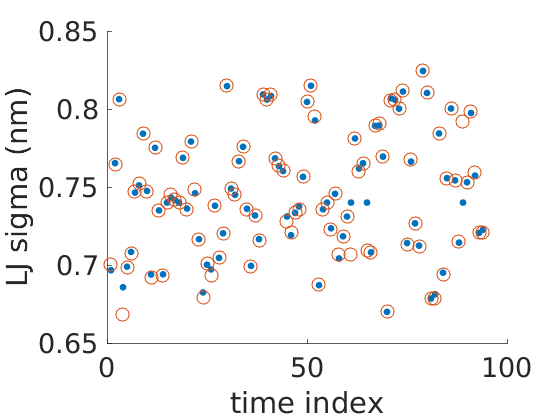

figure()
hold on
plot(1:size(betas,1),betas(:,2),'.','markersize',15)
plot(1:size(betas,1),beta1s,'o','markersize',10)
set(gca,'fontsize',20)
xlabel('time index')
ylabel('LJ sigma (nm)')

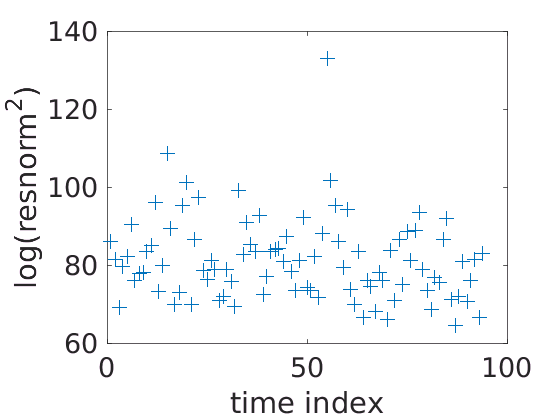

figure()
plot(1:size(betas,1),log(Jsums(:,2)),'+','markersize',10)
set(gca,'fontsize',20)
xlabel('time index')
ylabel('log(resnorm^2)')

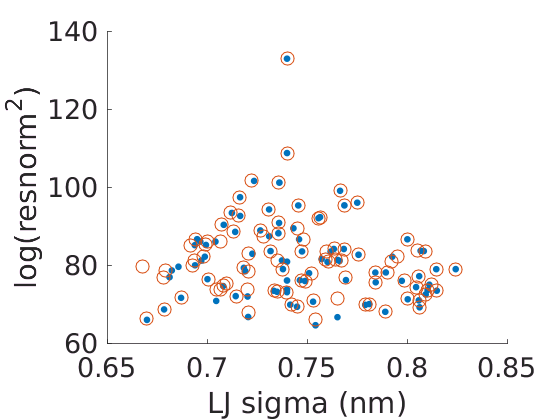

figure()
hold on
plot(betas(:,2),log(Jsums(:,2)),'.','markersize',15)
plot(beta1s,log(Jsum1s),'o','markersize',10)
set(gca,'fontsize',20)
xlabel('LJ sigma (nm)')
ylabel('log(resnorm^2)')

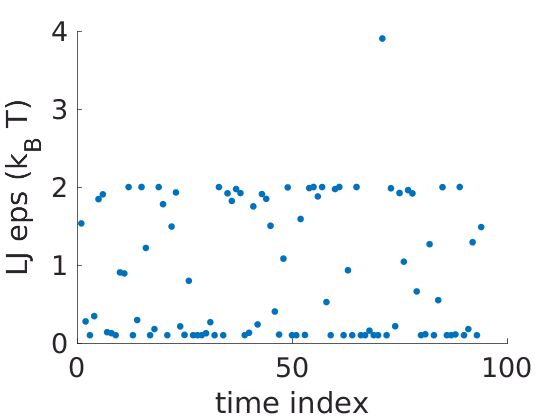

figure()
hold on
plot(1:size(betas,1),betas(:,1),'.','markersize',15)
set(gca,'fontsize',20)
xlabel('time index')
ylabel('LJ eps (k_B T)')

%ylim([-1 1])
figure()
plot(1:size(betas,1),log(Jsums(:,1)),'+','markersize',10)
set(gca,'fontsize',20)
xlabel('time index')
ylabel('log(resnorm^2)')

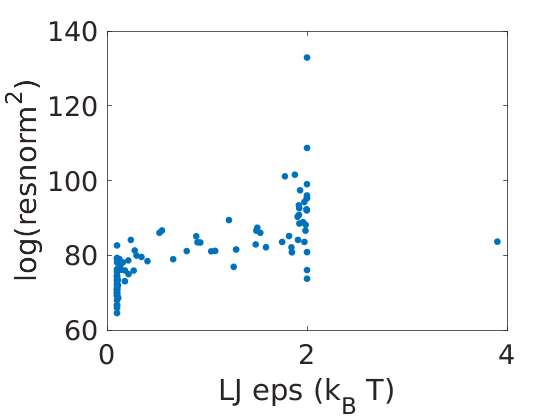

figure()
plot(betas(:,1),log(Jsums(:,1)),'.','markersize',15)
set(gca,'fontsize',20)
xlabel('LJ eps (k_B T)')
ylabel('log(resnorm^2)')

fprintf('The mean radius from 1 parameter fit is: %f +/- %f\n',mean(beta1s)/(2^(5/6)),std(beta1s)/(2^(5/6)));

Undefined function 'vifprintf' for input arguments of type 'char'.


fprintf('The mean radius from 2 parameter fit is: %f +/- %f\n',mean(betas(:,2))/(2^(5/6)),std(betas(:,2))/(2^(5/6)));
fprintf('The mean well depth from 2 parameter fit is: %f +/- %f\n',mean(betas(:,1)),std(betas(:,1)));